# Giraffe ADC Testbench

## Serial 串口的申请与调用

serialportlist

ans = "COM4"


baudrate = 256000;
% data_in = zeros();
    
s = serialport("COM4",baudrate)

s =   Serialport - 属性:

                 Port: "COM4"
             BaudRate: 256000
    NumBytesAvailable: 0

  Show all properties, functions


data = read(s,4*10000,'uint8');
% configureTerminator(s,"CR")  
% configureCallback(s,"terminator",@serial_callback) 
% configureCallback(s,"byte",1 ,@serial_callback)
% pause 
% data_serial = zeros()

if (s.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

## 串口数据后处理


% 将uint8 -> dec 
% data_origin = dec2bin(s.UserData); 
% data_origin = dec2bin(data(1:400000));
data_origin = dec2bin(data);
% data_tag = data_origin(:,1:2);


% if (sum(mod(find(data_tag=='11'), 4)) > 0 )
%     disp("Data Missing!");
%     index = find(data_tag == '11');
%     index_mod = mod(index, 4);
%     fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 3))
%     
% else
%     disp("Data Right!");
% end
clear s;

data_sign = str2num(data_origin(:,1));
data_value = data_origin(:,2:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign;
N_Sample = length(data_value) / 4;
data_N4 = reshape(data_value, [4, N_Sample])'

data_N4 =    -31    31   -31    31
   -20    31   -29    31
   -18    31   -30    31
   -19    31   -30    31
   -20    31   -29    31
   -20    31   -29    31
   -20    31   -29    31
   -20    31   -29    31
   -20    31   -29    31
   -20    31   -29    31


## AC Low Speed

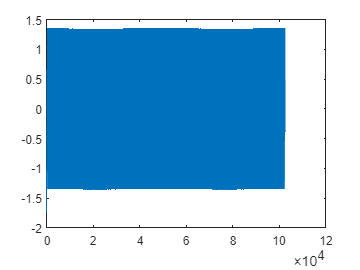

Vref = 1.8;
N_SUB = 5;
LSB_SUB = Vref / 2^N_SUB;

fclock = 5E6 / 1;           % clk_adc = 10kHz;
% fprintf("Number of Sample Points: 64 *  16 tiems average;")
fs = fclock / 25;                % sample rate = 200Hz;
fin = 1/256*fs;                   % fin = 5/64*fs;

Vout_N4 = data_N4 * LSB_SUB;
% Vout_N4 = Vout_N4(1:100000, :);
% N_Sample = 100000;
% ~~~~~~~~~~~~~~~ Flash ~~~~~~~~~~~~~~~
figure
plot(Vout_N4(:,1));

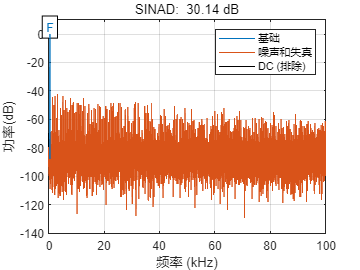

sinad(Vout_N4(:,1), fs);

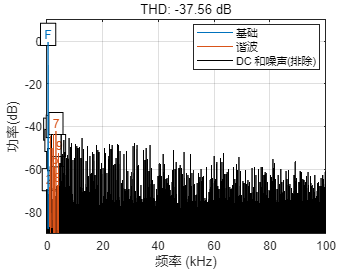

ans = -37.5625

thd(Vout_N4(:,1), fs, 9, "aliased")

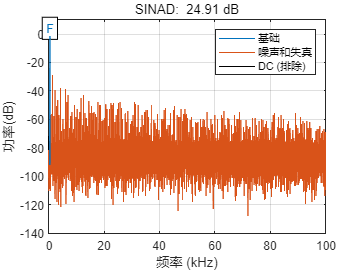

ans = 24.9142

% ~~~~~~~~~~~~~~~ without calibration ~~~~~~~~~~~~~~~
Vout_without_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
sinad(Vout_without_calib, fs)

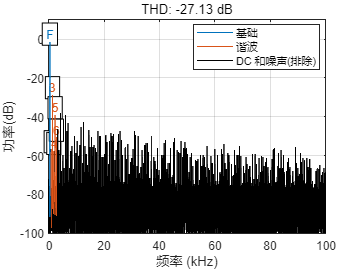

ans = -27.1266

thd(Vout_without_calib, fs, 'aliased')

## Calibration

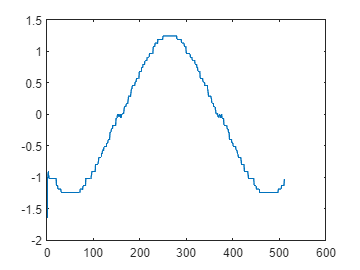

% ~~~~~~~~~~~~~~~ plus calibration ~~~~~~~~~~~~~~~
Vout_plus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_plus_calib(i) = Calib_Gain(Vout_N4(i,:), abs(GAIN_PLUS));
end
plot(Vout_plus_calib(1:512,1));

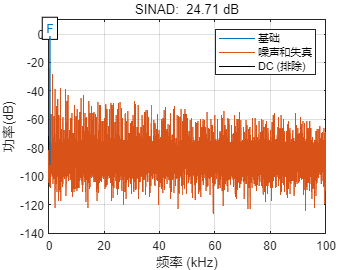

ans = 24.7062

sinad(Vout_plus_calib, fs)

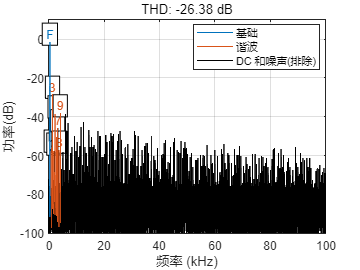

ans = -26.3776

thd(Vout_plus_calib, fs, 9, 'aliased')

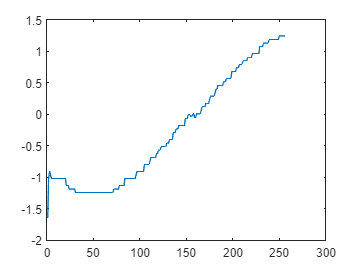



% ~~~~~~~~~~~~~~~ minus calibration ~~~~~~~~~~~~~~~     
Vout_minus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_minus_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN_MIN);
end
plot(Vout_minus_calib(1:256,1));

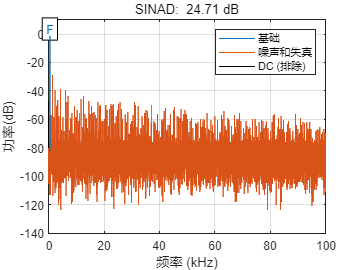

ans = 24.7054

V0 = repmat(Vout_minus_calib, [1,1]);
V1 = V0 .* hamming(length(V0));
sinad(V1, fs)

ans = -26.3776

thd(Vout_minus_calib, fs, 9, 'aliased')

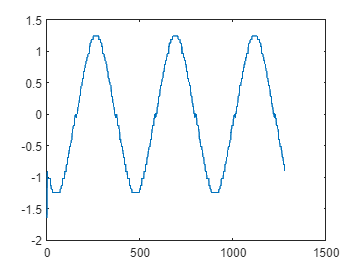


% ~~~~~~~~~~~~~~~ mean calibration ~~~~~~~~~~~~~~~
Vout_mean_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), mean(abs([GAIN_MIN, GAIN_PLUS])));
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_mean_calib(1:1280,1));

ans = 24.7062

sinad(Vout_mean_calib, fs)

% thd(Vout_mean_calib , fs, 9, 'aliased')
% sfdr(Vout_mean_calib, fs)

(max(Vout_mean_calib) - min(Vout_mean_calib)) / 2

ans = 1.4410


% % w=hamming(N_Sample);
% % Vout_windowed = w.*Vout_mean_calib;
% % 
% % thd(Vout_windowed , fs, 9, 'aliased')
% % sinad(Vout_windowed, fs)
% LSB = Vref / 2^15;
% negetive = Vout_mean_calib < 0;
% quan2 = floor(Vout_mean_calib / LSB) + negetive;
% 
% Vout_quan = quan2 .* LSB;
% sinad(Vout_quan, fs)
% thd(Vout_quan , fs, 9, 'aliased')
% sfdr(Vout_quan, fs)
%  max(Vout_mean_calib)
%  min(Vout_mean_calib)   

## Data Process

% figure
% periodogram(Vout_mean_calib, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% 
% [pxx_1, f] = periodogram(Vout_mean_calib, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% [pxx_2, f] = periodogram(Vout_No_Input, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% figure
% plot(f, 10*log10(pxx_1), f, 10*log10(pxx_2));
% xlabel('Frequency [Hz]');
% ylabel('PSD [dB/Hz]')
% grid on
% legend(["with input"; "without input"])


% title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])

## Gain Sweep

% gain_sweep = 14:0.01:17;
% sinad_sweep = zeros(size(gain_sweep));
% thd_sweep = zeros(size(gain_sweep));
% for j = 1:length(gain_sweep)
%     Vout_sweep = zeros(N_Sample, 1);
%     for i=1:N_Sample
%         Vout_sweep(i) = Calib_Gain(Vout_N4(i,:), gain_sweep(j));
%     end
%     sinad_sweep(j) = sinad(Vout_sweep, fs);
%     thd_sweep(j) = thd(Vout_sweep, fs, 7, 'aliased');
% end


%     max(sinad_sweep)
%     min(thd_sweep)
%     sinad_index = find(sinad_sweep == max(sinad_sweep))
%     thd_index = find(thd_sweep == min(thd_sweep))
%     gain_sweep(sinad_index)
%     gain_sweep(thd_index)
%     figure
%     yyaxis left
%     plot(gain_sweep, sinad_sweep);
%     
%     ylabel("SINAD [dB]")
%     yyaxis right
%     plot(gain_sweep ,thd_sweep)
%     ylabel("THD [dB]")
%     xlabel("Gain")
%     grid on


## Noise Analysis

% [f, p, NV_rms] = Noise_PSD(Vout_without_calib, fs);
% figure
% plot(f, 10*log10(p));
% grid on;
% % Periodgram
% 
% periodogram(Vout_without_calib, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% 
% PsdSectionLength = 2048;
% NumSection = N_Sample / PsdSectionLength;
% PSD = [];
% for i=1:NumSection
%     index_head = (i-1)*PsdSectionLength+1;
%     index_tail = i*PsdSectionLength;
%     [pxx,f ] = periodogram(Vout_without_calib(index_head:index_tail), ...
%         hann(PsdSectionLength), N_Sample, fs, 'PSD');
%     PSD = [PSD,pxx];
% end
% PSD_AVE = mean(PSD,2);
% figure
% plot(f, 10*log10(PSD_AVE));
% xlabel('Frequency [Hz]');
% ylabel('PSD [dB/Hz]')
% grid on
% %integrated Noise
% Noise_RMS = sqrt(sum(PSD_AVE*(fs/(N_Sample))))

% Integrated Noise in Power
Noise_RMS = pow2db(var(Vout_mean_calib))

Noise_RMS = -1.2500


% Periodgram

[pxx_1, f] = periodogram(Vout_mean_calib, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');
pxx_1(1)=  0;
pow2db(sum(pxx_1 * (fs/N_Sample)) )

ans = -1.2500

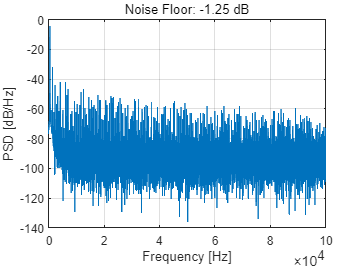

figure
plot(f, 10*log10(pxx_1));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])

% pxx(1) = 0;
% % pow2db(sum(p1 * (fs/N_Sample)))
% offset = mag2db(mean(Vout_without_calib))

% function serial_callback(src,evt)
%     data = readline(src);
% %     disp(data)
%     src.UserData = data;
% end


function serial_callback(s, ~)
%     global data_serial;
    data = read(s, 1, 'uint8');
    s.UserData = [s.UserData; data];
    % 通过串口对象自身将读取数据带回；
    disp(data)
end